# DC Microgrid Simulator

clear all
close all
clc

rng(12)

numOfDGs = 7;
% numOfLines = 6;
threshold = 0.7;

## Generate a random physical topology

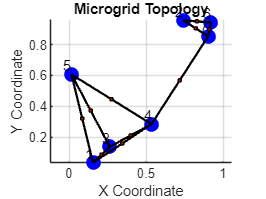

Coordinates of DGs:
    0.1542    0.0334
    0.7400    0.9569
    0.2633    0.1372
    0.5337    0.2838
    0.0146    0.6061
    0.9187    0.9442
    0.9007    0.8527

Adjacency Matrix:
     0     0     1     1     1     0     0
     0     0     0     0     0     1     1
    -1     0     0     1     1     0     0
    -1     0    -1     0     1     0     1
    -1     0    -1    -1     0     0     0
     0    -1     0     0     0     0     1
     0    -1     0    -1     0    -1     0

B_il Matrix:
     1     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
    -1     0     0     0     0     1     1     0     0     0
     0    -1     0     0     0    -1     0     1     1     0
     0     0    -1     0     0     0    -1    -1     0     0
     0     0     0    -1     0     0     0     0     0     1
     0     0     0     0    -1     0     0     0    -1    -1



coords =     0.1542    0.0334
    0.7400    0.9569
    0.2633    0.1372
    0.5337    0.2838
    0.0146    0.6061
    0.9187    0.9442
    0.9007    0.8527


adjMatrix =      0     0     1     1     1     0     0
     0     0     0     0     0     1     1
    -1     0     0     1     1     0     0
    -1     0    -1     0     1     0     1
    -1     0    -1    -1     0     0     0
     0    -1     0     0     0     0     1
     0    -1     0    -1     0    -1     0


B_il =      1     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
    -1     0     0     0     0     1     1     0     0     0
     0    -1     0     0     0    -1     0     1     1     0
     0     0    -1     0     0     0    -1    -1     0     0
     0     0     0    -1     0     0     0     0     0     1
     0     0     0     0    -1     0     0     0    -1    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.

[coords, adjMatrix, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0);
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     3.3959   11.0286   -3.6329
   11.0286   65.0741  -11.9192
   -3.6329  -11.9192   13.1721


KVal =  -156.2803   11.2912   -3.8482


LVal =  -122.8277   17.6585  -18.1894


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.2987   10.8687   -3.5539
   10.8687   65.0760  -11.8404
   -3.5539  -11.8404   13.0511


KVal =  -109.5657   11.8768   -3.8633


LVal =   -89.0484   12.6828  -13.0378


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4340   11.0953   -3.6644
   11.0953   65.0919  -11.9494
   -3.6644  -11.9494   13.2200


KVal =  -125.0587   11.7213   -3.9026


LVal =   -97.7430   14.1633  -14.5859


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4471   11.1162   -3.6749
   11.1162   65.0904  -11.9596
   -3.6749  -11.9596   13.2360


KVal =  -207.4489   11.4819   -3.9429


LVal =  -160.3957   23.1804  -23.8856


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.5001   11.1968   -3.7168
   11.1968   65.0682  -12.0003
   -3.7168  -12.0003   13.2993


KVal =  -147.8368   12.0468   -4.0213


LVal =  -113.1443   16.5158  -17.0202


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4701   11.1378   -3.6911
   11.1378   65.0254  -11.9772
   -3.6911  -11.9772   13.2604


KVal =  -186.3430   11.5107   -3.9761


LVal =  -142.9583   20.7268  -21.3725


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.5043   11.2012   -3.7198
   11.2012   65.0590  -12.0035
   -3.7198  -12.0035   13.3038


KVal =  -157.7776   11.7738   -3.9870


LVal =  -120.4189   17.5712  -18.1152


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0525

nuBarVal = -100.0000

rhoBarVal = 0.0692

status = logical
   1


PBarVal = 0.0415

nuBarVal = -100.0000

rhoBarVal = 0.0827

status = logical
   1


PBarVal = 0.0407

nuBarVal = -100.0000

rhoBarVal = 0.0853

status = logical
   1


PBarVal = 0.0307

nuBarVal = -100.0000

rhoBarVal = 0.0854

status = logical
   1


PBarVal = 0.0448

nuBarVal = -100.0000

rhoBarVal = 0.0643

status = logical
   1


PBarVal = 0.0322

nuBarVal = -100.0000

rhoBarVal = 0.0959

status = logical
   1


PBarVal = 0.0342

nuBarVal = -100.0000

rhoBarVal = 0.0759

status = logical
   1


PBarVal = 0.0389

nuBarVal = -100.0000

rhoBarVal = 0.0628

status = logical
   1


PBarVal = 0.0305

nuBarVal = -100.0000

rhoBarVal = 0.0826

status = logical
   1


PBarVal = 0.0554

nuBarVal = -100.0000

rhoBarVal = 0.0919

status = logical
   1



% R_DG{i} vs DG{i}.R

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines B_il

## Centralized Local Controller Design

[DG,Line] = centralizedLocalControlDesign(DG,Line,B_il) % topologyMetrics may be the B matrix 

Unrecognized function or variable 'numOfDGs'.

Error in centralizedLocalControlDesign (line 5)
for i = 1:1:numOfDGs

% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 